BPNNGeneParaForecasting

Shuai Yang

2023/3/2

采用 newff 函数 先对数据进行归一化

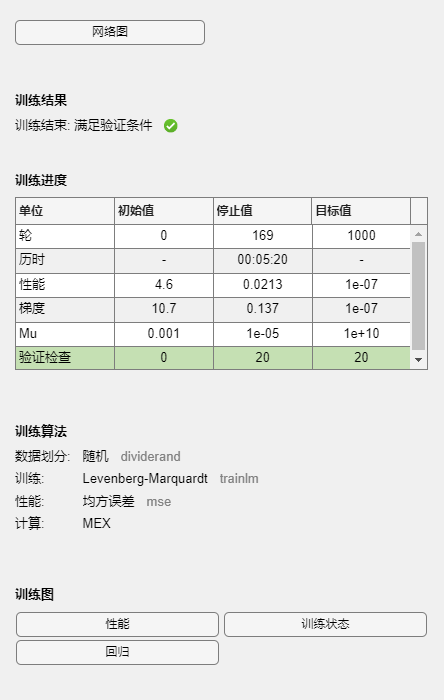

%% 
close all
clear
clc
% warning off

load('F.mat');

idx = randperm(size(F,1));
% 训练集
P_train = F(idx(1:end-200),1:51)';
T_train = F(idx(1:end-200),52:end)';
M = size(P_train,2);% 训练集数目
% 测试集
P_test = F(idx(end-199:end),1:51)';
T_test = F(idx(end-199:end),52:end)';
N = size(P_test,2);% 训练集数目


% 归一化
[p_train,ps_input] = mapminmax(P_train,-1,1);
p_test = mapminmax('apply',P_test,ps_input);

[t_train,ps_output] = mapminmax(T_train,-1,1);
t_test = mapminmax('apply',T_test,ps_output);

% 创建网络1
net = newff(p_train,t_train,[22,22,22]);

%创建网络2
% net = feedforwardnet([22,22,22,22]);

% 设置训练参数
net.trainParam.epochs = 1000;   % 迭代次数
net.trainParam.goal = 1e-7;     % 误差阈值
net.trainParam.max_fail = 20;   % 交叉验证次数


% view(net);

% 训练网络
net = train(net, p_train, t_train);

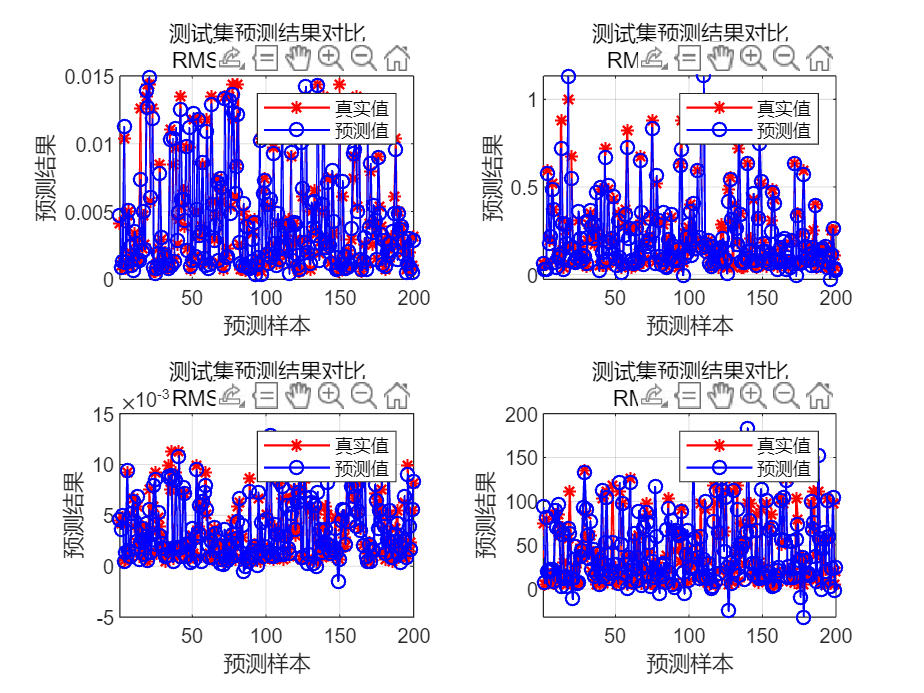

% 仿真测试
t_sim1 = sim(net, p_train);
t_sim2 = sim(net, p_test);
% 数据反归一化
T_sim1 = mapminmax('reverse',t_sim1,ps_output);
T_sim2 = mapminmax('reverse',t_sim2,ps_output);

% 均方误差
error1 = NaN(1,size(T_test,1));
error2 = NaN(1,size(T_test,1));
for iPre = 1:size(T_test,1)
    error1(iPre) = sqrt(sum((T_sim1((iPre),:) - T_train((iPre),:)).^2)./M);
    error2(iPre) = sqrt(sum((T_sim2((iPre),:) - T_test((iPre),:)).^2)./N);
end

% % plot 可视化
% f1 = figure;
% plot(1:M, T_train, 'r-*', 1:M, T_sim1,'b-o','LineWidth', 1)
% legend('真实值','预测值')
% xlabel('预测样本')
% ylabel('预测结果')
% string = {'训练集预测结果对比';['RMSE=',num2str(error1)]};
% title(string)
% xlim([1,M])
% grid on

% plot 可视化
f2 = figure;
for iPre = 1:size(T_test,1)
    nexttile
    plot(1:N, T_test(iPre,:), 'r-*', 1:N, T_sim2(iPre,:),'b-o','LineWidth', 1)
    legend('真实值','预测值')
    xlabel('预测样本')
    ylabel('预测结果')
    string = {'测试集预测结果对比';['RMSE=',num2str(error1(iPre))]};
    title(string)
    xlim([1,N])
    grid on
end

% 数据预测
load('predData_GenePara.mat')
N_test = predData(:,1:51)';
n_test = mapminmax('apply',N_test,ps_input);
t_sim3 = sim(net, n_test);
T_sim3 = mapminmax('reverse',t_sim3,ps_output);
T_true = predData(:,52:end)';


title_strings = {'gamma','beta','alpha','lambda'}

title_strings = 1×4 cell 数组
    {'gamma'}    {'beta'}    {'alpha'}    {'lambda'}


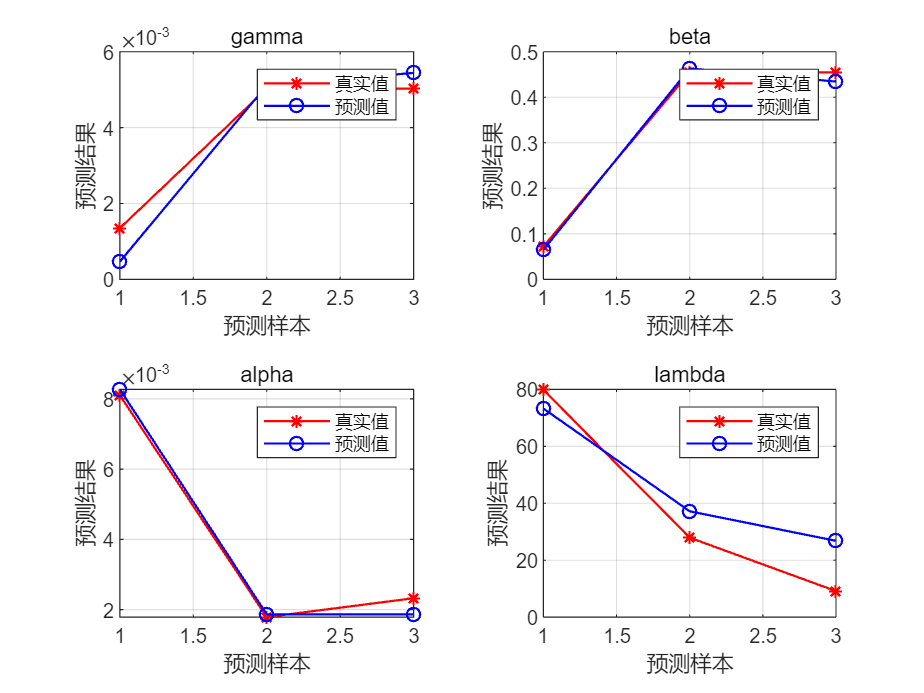

N = size(T_sim3,2);% 3个样本
f = figure;
for iPre = 1:size(T_sim3,1) % 预测参数数目
    nexttile
    plot(1:N, T_true(iPre,:), 'r-*', 1:N, T_sim3(iPre,:),'b-o','LineWidth', 1)
    legend('真实值','预测值')
    xlabel('预测样本')
    ylabel('预测结果')
    title(title_strings(iPre))
    xlim([1,N])
    grid on
end

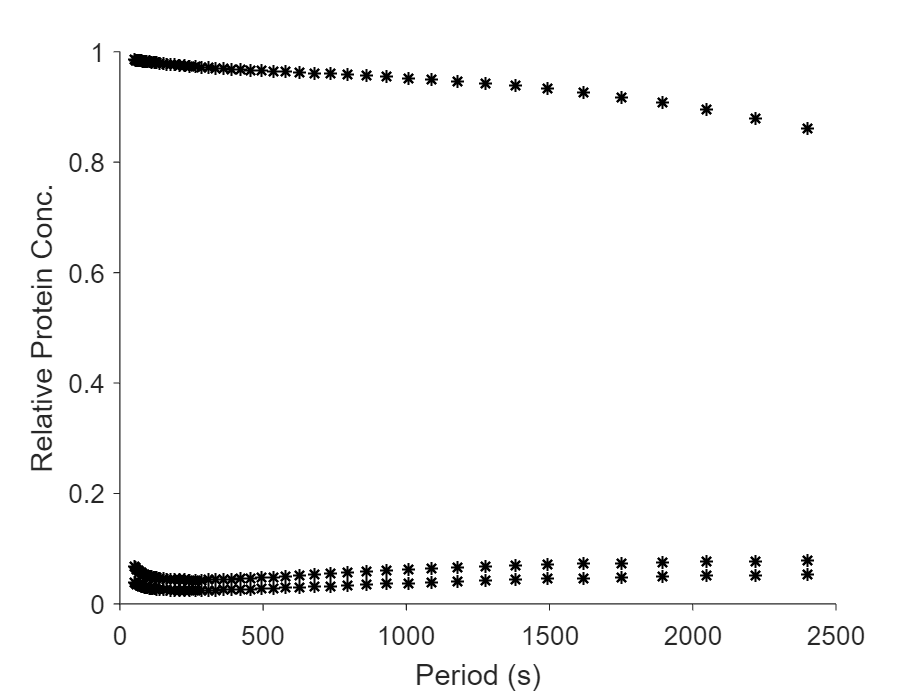


Tset = logspace(log10(50),log10(2400),50);
f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset,predData(:,1:50),'k-*',...
    'LineStyle','none','LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')